We look at the balance between the axial spring and the radial spring to lock the claw in position

clear
clf

considering a constant spring constant we get the pull of one **axial spring** from SODEMANN

k_axial = 0.29e3; % N/mm --> N/m % max kraft 47,43, max vandring 140,97, total lenth 229,87
% varenummer 	E07500633500S trækfjeder SODEMANN
x_axial = 140e-3; % udspændt fjeder til træk af claw
F_spring_axial = k_axial * x_axial

F_spring_axial = 40.6000

considering a constant spring constant we get the push of one **radial spring** from SODEMANN

theta = 15; %angle on ball lock
r_ball = 5e-3; %radius of the ball lock
% r_ball = 7.5e-3; %radius of the ball lock

k_radial = 12.16e3; % N/mm --> N/m %max compresion 13.80, total length 27.00; max force 169,66
% varenummer 12410
% alternatvi C06000981750M	 
% k_radial = 1e3;%24.22e3

x_radial = r_ball*sind(theta); %3; % mm compressed spring to hold
x_radial_mm = x_radial*1e3

x_radial_mm = 1.2941

F_spring_radial = k_radial*x_radial

F_spring_radial = 15.7362

Frication acting on the calw is devided in to two kinds that are added up.

- Due to gravity we find

g = 9.82;
m_claw = 1; %kg <--------- differ between claws
f_s = 0.30;
F_claw_fric = g * m_claw * f_s

F_claw_fric = 2.9460

- Due to the process of sliding over the ball also ads the friction of the ball pushing up. 

The normal force comes from the spring pushing up and it veries with movement. But since the normal force is stronger then the friction force we will alway have more force to hold with less angle on theta.

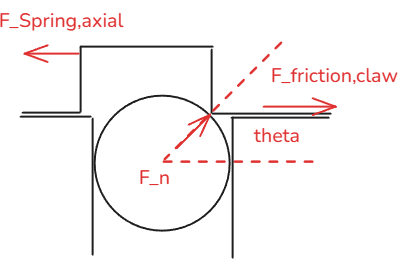

F_n_y = F_spring_radial

F_n_y = 15.7362

F_ball_fric = F_n_y * f_s % sind(theta) * F__n * f_s

F_ball_fric = 4.7209

We sum the forces in the x-direction

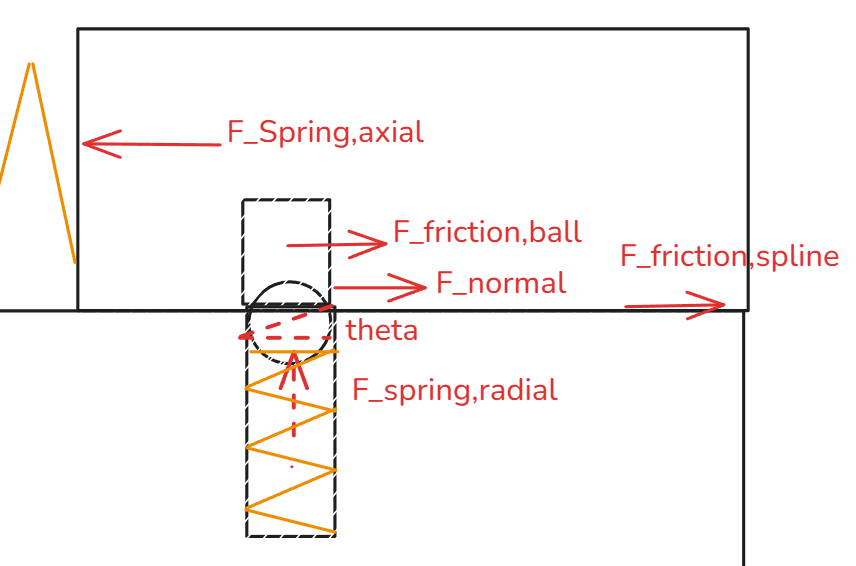

syms F_n  %F_spring_radial
F_x_eq_static = 0 == F_spring_axial - F_ball_fric - F_claw_fric - F_n * cosd(theta); %  F_claw_fric

disp("Normal force requried for static in the x direction")

Normal force requried for static in the x direction


F_n_sol_static = solve(F_x_eq_static, F_n);
F_n_static1 = double(F_n_sol_static)

F_n_static1 = 34.0949

F_n_x_static1 = F_n_static1 * cosd(theta)

F_n_x_static1 = 32.9331

We sum the forces in the y-direction

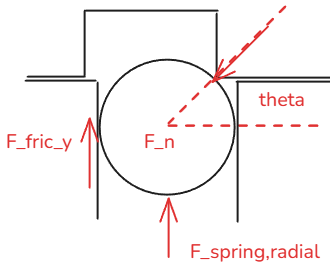

disp("Normal force requried for static in the y direction")

Normal force requried for static in the y direction


F_fric_y_static = F_n * cosd(theta) * f_s;

F_y_eq_static = 0 == F_n * cosd(theta) - F_spring_radial - F_fric_y_static;
F_n_sol_static2 = solve(F_y_eq_static, F_n);
F_n_static2 = double(F_n_sol_static2)

F_n_static2 = 23.2733

F_n_x_static2 = F_n_static2 * cosd(theta)

F_n_x_static2 = 22.4803

Plot

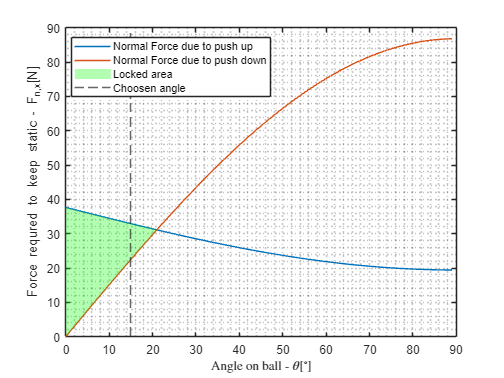

thetas = 0:1:89; %angle on ball lock
for i = 1:length(thetas)
    x_radial = r_ball*sind(thetas(i)); %3; % mm compressed spring to hold
    F_spring_radial = k_radial*x_radial;
    
    F_n_y = F_spring_radial;
    F_ball_fric = F_n_y * f_s; % sind(theta) * F__n * f_s
    
    syms F_n  %F_spring_radial
    F_x_eq_static = 0 == F_spring_axial - F_ball_fric - F_claw_fric - F_n * cosd(thetas(i)); %  F_claw_fric
    
    % Push up normal force
    F_n_sol_static = solve(F_x_eq_static, F_n);
    F_n_static1 = double(F_n_sol_static);
    F_n_static1s(i) = F_n_static1;
    F_n_x_static1(i) = F_n_static1 * cosd(thetas(i));
    
    % Push down normal force
    F_fric_y_static = F_n * cosd(thetas(i)) * f_s;
    F_y_eq_static = 0 == F_n * cosd(thetas(i)) - F_spring_radial - F_fric_y_static;
    F_n_sol_static2 = solve(F_y_eq_static, F_n);
    F_n_static2 = double(F_n_sol_static2);
    F_n_static2s(i) = F_n_static2;
    F_n_x_static2(i) = F_n_static2 * cosd(thetas(i));
end

plot(thetas, F_n_x_static1, DisplayName="Normal Force due to push up")
hold on
plot(thetas, F_n_x_static2, DisplayName="Normal Force due to push down")

% Identify the region where F_n_x_static1 > F_n_x_static2
meet_index = find(F_n_x_static1 <= F_n_x_static2, 1);

if isempty(meet_index)
    % If the curves never meet, fill up to the last point
    meet_index = length(thetas);
end

% the filled area
x_fill = [thetas(1:meet_index), fliplr(thetas(1:meet_index))];
y_fill = [F_n_x_static1(1:meet_index), fliplr(F_n_x_static2(1:meet_index))];
fill(x_fill, y_fill, 'green', 'FaceAlpha', 0.3, 'EdgeColor', 'none', DisplayName="Locked area");

xline(theta,'--', DisplayName="Choosen angle")
xlabel("Angle on ball - $\theta [^{\circ} ]$", Interpreter="latex")
ylabel("Force requred to keep static - F_{n,x}[N]")
grid("minor")
legend(location='best')
hold off


% plot(thetas, F_n_static1s, DisplayName="Axial normal force needed")
% hold on
% plot(thetas, F_n_static2s, DisplayName="Radial normal force needed")
% xline(theta,'--', DisplayName="Choosen angle")
% xlabel("Angle on ball - $\theta [^{\circ} ]$", Interpreter="latex")
% ylabel("Force requred to keep static - F_{n}[N]")
% grid("minor")
% legend(location='best')
% hold off

For dynamik

syms F_n F_x_move  %F_spring_radial
F_x_eq = F_x_move == F_spring_axial - F_ball_fric - F_claw_fric - F_n * cosd(theta); %  F_claw_fric

F_n_y = F_spring_axial * sind(theta)

F_n_y = 39.9832

F_fric_y = F_n * cosd(theta) * f_s

$$F\_fric\_y = \frac{8758868924224755\,F_{n}}{144115188075855872}$$

F_y_eq = 0 == F_n * cosd(theta) - F_spring_radial - F_fric_y;

[F_n_sol, F_x_move_sol] = solve([F_x_eq, F_y_eq], [F_n, F_x_move]);
F_n = double(F_n_sol)

F_n = 318.2898

F_x_move = double(F_x_move_sol)

F_x_move = -30.6815

F_n_x = F_n * cosd(theta)

F_n_x = 55.2704




phi = 45

phi = 45


n_stack = 2; %number of stacked disc springs
F_realese = 553; % N = k * x  % max vandirng 0,53 ;frilængde 1,40, ved belastning 0,88, D_udvendig = 18,00mm
% tallerken fjeder vare nummer 1800-620-70

F_realease_x = sind(phi) * F_realese

F_realease_x = 391.0300

F_realese_ball = F_realease_x / cos(theta)

F_realese_ball = -3.5423e+03

F_realease_ball_y = sind(theta) * F_realese_ball

F_realease_ball_y = -3.4885e+03

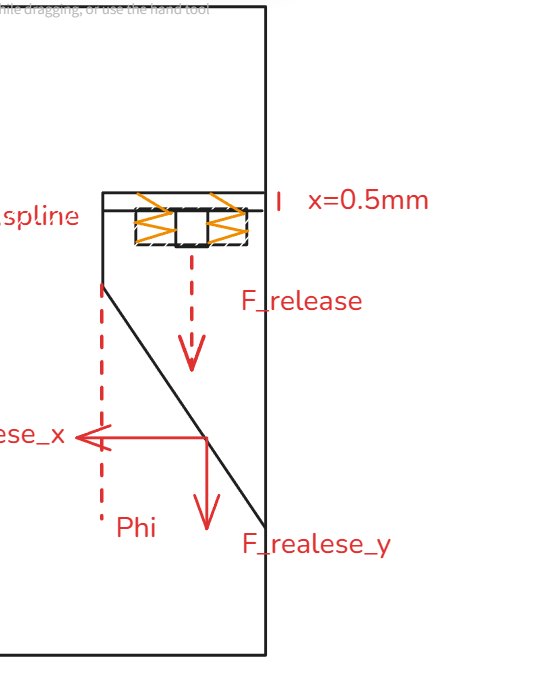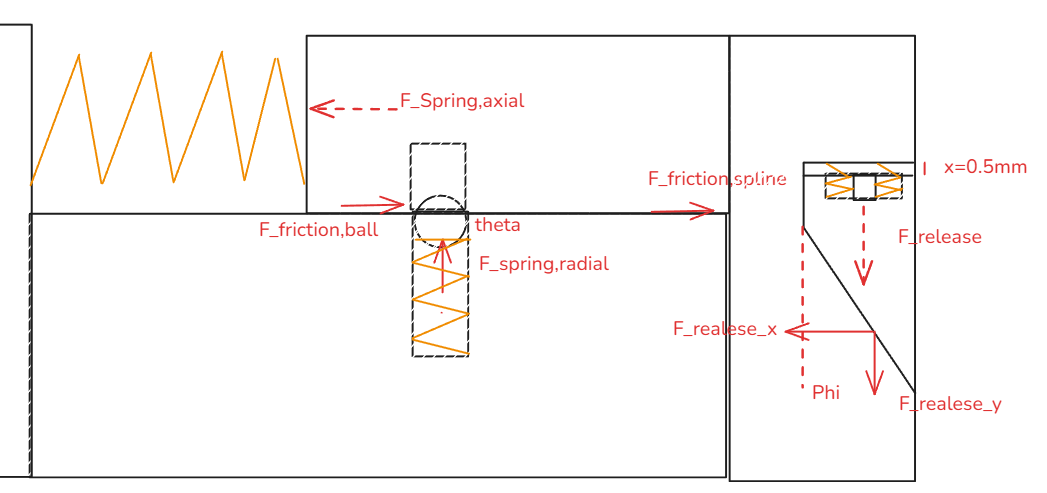

syms a
eq_x_dyn = m_claw * a == F_spring_radial - F_claw_fric - F_ball_fric

$$eq\_x\_dyn = a=\frac{1401376753090139}{70368744177664}$$


a = double(solve(eq_x_dyn, a))

a = 19.9148


r = 0.1; % center of contact area
s = 0.53e-3;
T = F_realese * r

T = 55.3000


W = F_realese * s

W = 0.2931


syms omega
% I = 1; % inertia of the test motor % HMC4 355L-2
% I = 3.68; % inertia of the test motor % HMC4 355L-2
% I = 12.79; % inertia of the test motor % HMC4 355L-2
I = 15.9356; % inertia of the test motor % HMC4 355L-2 <--------- differ from motor to motor
W_eq = W == 1/2 * I * omega^2;
omega_sol = solve(W_eq, omega);
omega = double(omega_sol(2))

omega = 0.1918

Dermed har jeg hastigheden ved slip, kraften aftager løbende i fjederen men antage at være tæt på F_realease_x i det kontakten slippes.

Couplings delen skal rejse 1 mm og tabet her negligeres

We see this as a totallly non-elastic collision because of the slow speeds and high moments of inertia.

m_rotor = 400 %                 <--------- differ from motor to motor

m_rotor = 400

u_rotor = r * omega

u_rotor = 0.0192

u_rotor_x = sind(phi) * u_rotor

u_rotor_x = 0.0136

% where u_claw = 0 since we are seeing it from the claws point of veiw.
v_claw_x = m_rotor * u_rotor_x / (m_rotor + m_claw) 

v_claw_x = 0.0135



E_kin_claw = 1/2 * m_claw * v_claw_x^2

E_kin_claw = 9.1503e-05


E_radial_spring = 1/2 * k_radial * (x_radial/1000)^2 * 2 %two springs

E_radial_spring = 1.0614e-07


E_axial_spring = 1/2 * k_axial * (x_axial/1000)^2 * 2 %two springs

E_axial_spring = 5.6840e-06

limits for pulling and pushing of a worker in canada [https://www.ccohs.ca/oshanswers/ergonomics/push1.html](https://www.ccohs.ca/oshanswers/ergonomics/push1.html)